clear all;
%bild=im2double(imread('rose.tif'));
bild=kreisBild(500,5);

Elapsed time is 0.017347 seconds.


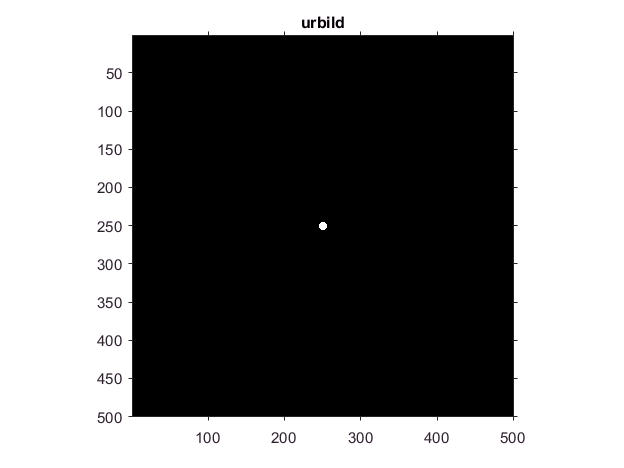

figure;
imshow(bild);
title('urbild'); figure;

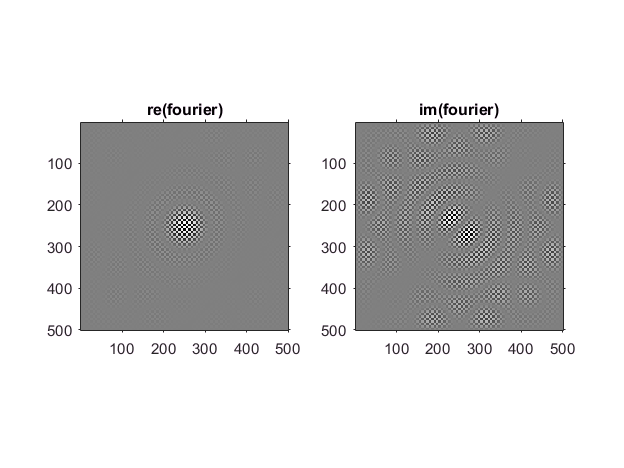


[H, B]=size(bild);
fourier=centerImage(fft2(bild)/numel(bild));

imshowCompl(fourier,'fourier');

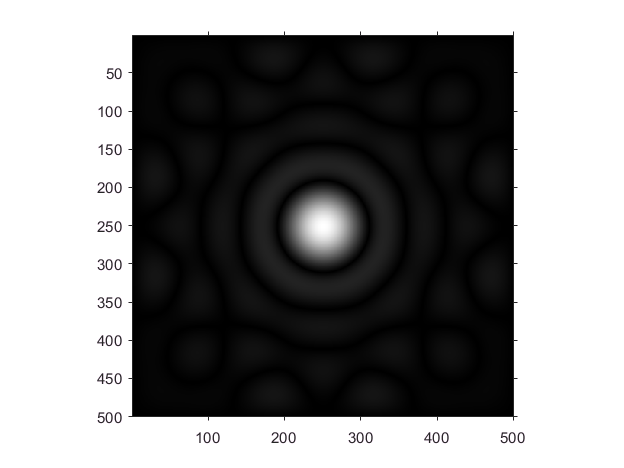

figure;
imshow(log(1+abs(fourier)),[]);

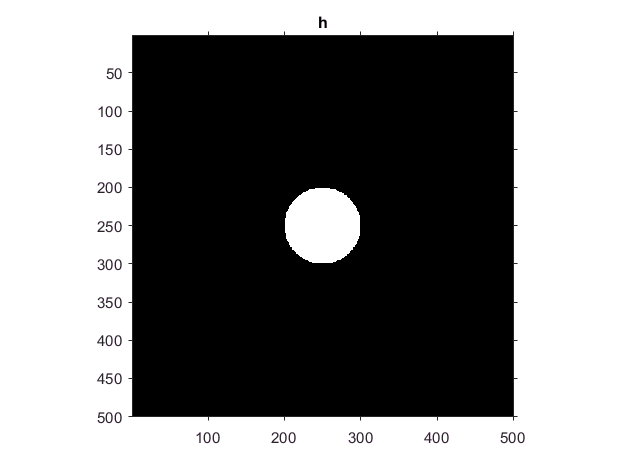


wert=50;
wert=wert^2;
h=ones(H,B)*255;
for j=1:H
    for k=1:B
%        fprintf('j:%.f k:%.f q:%.f ', j, k, (j-H/2)^2+(k-B/2)^2);
        if (j-H/2)^2+(k-B/2)^2 >= wert
            fourier(j, k)=0;
            h(j,k)=0;
%            fprintf('%.f %.f\n',j,k);
        end
    end
end
figure;
imshow(h);
title('h');

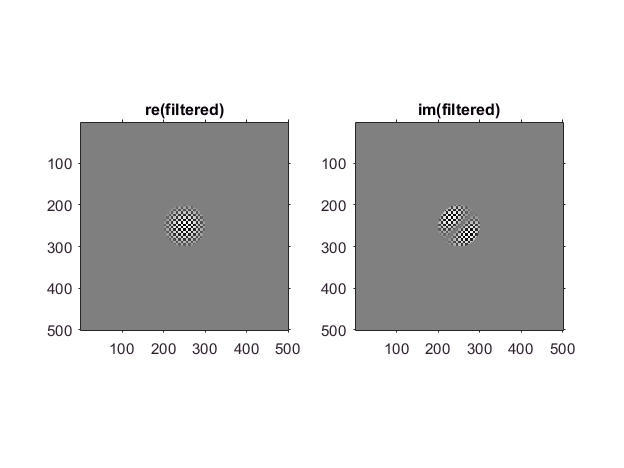


imshowCompl(fourier, 'filtered');



fourier=deCenterImage(fourier);
Ifourier = ifft2(fourier);


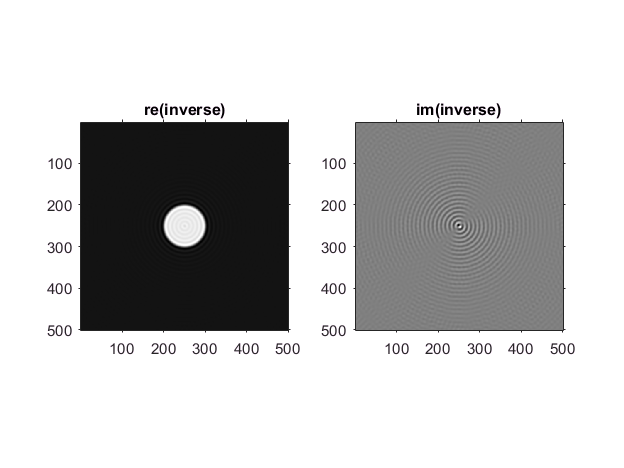

imshowCompl(Ifourier,'inverse');

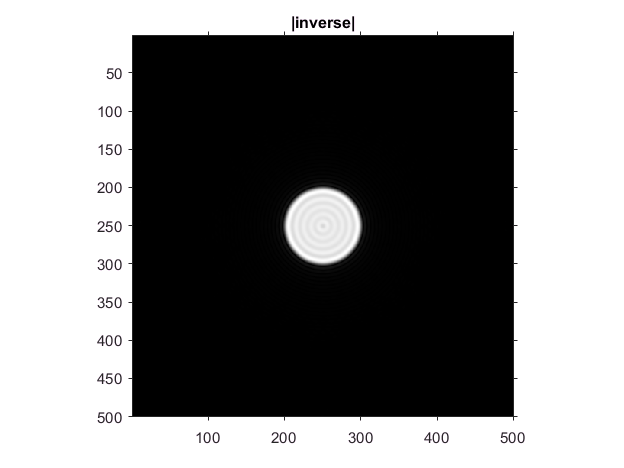


figure;
imshow(abs(Ifourier),[]);
title('|inverse|');

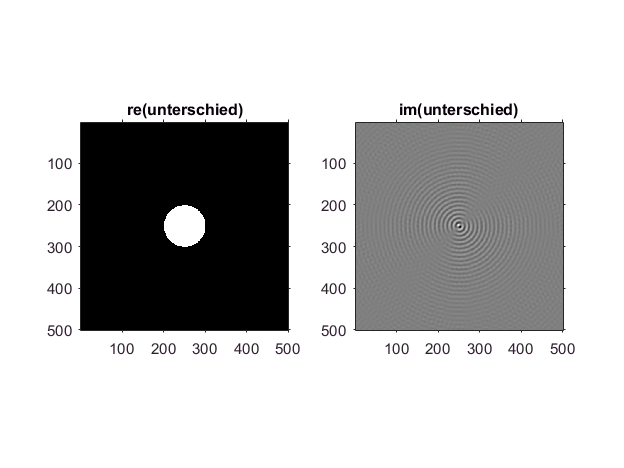


unterschied = bild - Ifourier;
imshowCompl(unterschied,'unterschied');

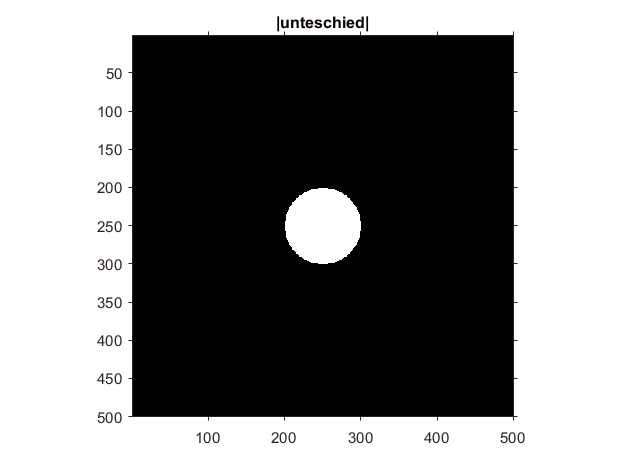


figure;
imshow(abs(unterschied),[]);
title('|unteschied|');